### Собственные числа и собственные значения матрицы

Действие матрицы A на элемент пространства х = [1; 2];

 % A = [2, 1; 1, 1];
  A = [0.5 0.6; 1 -1];
 
x = [1;2];
y = A*x;

xv = vector(x'); yv = vector(y');

xv.plot
yv.plot(2,2)
hold on
box on

Действие матрицы A на элемент пространства х = [1; -1];

x = [1;-1];
y = A*x;

xv = vector(x'); yv = vector(y');

figure
xv.plot
yv.plot(2,2)
hold on
box on

#### Инвариантные подпространства

Действие матрицы A на элемент пространства х = [0.8773; 0.4799];

figure
[d,v] = eig(A);

x = [d(1,1);d(2,1)];
y = A*x;
Y = vector(y');
X = vector(x');
if norm(x)>norm(y)
    X.plot(3,1)
    Y.plot(2,2)    
else    
    Y.plot(3,2)
    X.plot
    
end
box on

### Инвариантные подпространства

figure
X.plot(2,1)
Y.plot(2,2)
x = linspace(-2.5,2.5);
y1 = d(2,1)/d(1,1)*x;
y2 = d(2,2)/d(1,2)*x;
plot(x,y1,'k.')
hold on
plot(x,y2,'k.')
if norm(Y.x) > norm(X.x)
    Y.plot(3,2)
    X.plot(2,1)
else
    X.plot(3,1)
    Y.plot(2,2)
end

box on
xlim([-2.5,2.5])
v = axis;
plot(v(1:2),[0 0],'k')
plot([0 0],v(3:4),'k')

Спектр матрицы

A = [2 1; 1 1];
% A = [0.5 0.6; 1 -1];
[V,s] = eig(A)

s - собственные числа

V - собственные вектора

### Спектральное разложение

B = V*s*V^-1;
x = [1;2];
y = A*x;

xv = vector(x'); yv = vector(y');
figure
xv.plot
yv.plot(3,2)
hold on
box on
y1 = V^-1*x;
Y1 = vector(y1');
figure
xv.plot(2,1);
hold on
box on
Y1.plot(2,2);
y2 = s*y1;
Y2 = vector(y2');
figure
Y1.plot(2,2);
hold on
box on
Y2.plot(2,3);
y3 = V*y2;
Y3 = vector(y3');
figure
Y2.plot(2,3);
hold on
box on
Y3.plot(2,4);

### Сингулярное разложение матрицы

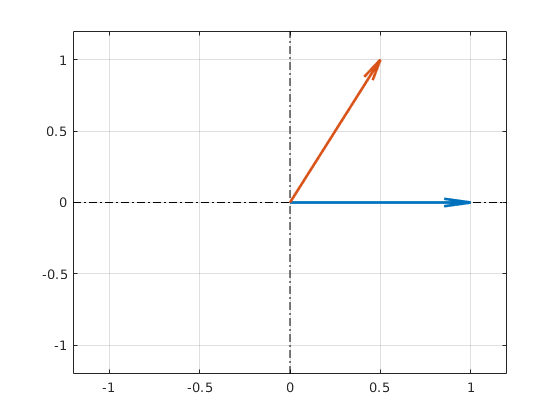

A = [0.5 0.6; 1 -1];
[U,S,V] = svd(A);
x = [1;0];
y = A*x;
X = vector(x');
Y = vector(y');
figure
box on
X.plot(2,1)
Y.plot(2,2)

y1 = V'*x;
y2 = S*y1;
y3 = U*y2;

Y1 = vector(y1');
Y2 = vector(y2');
Y3 = vector(y3');

Действие матрицы V на элемент x

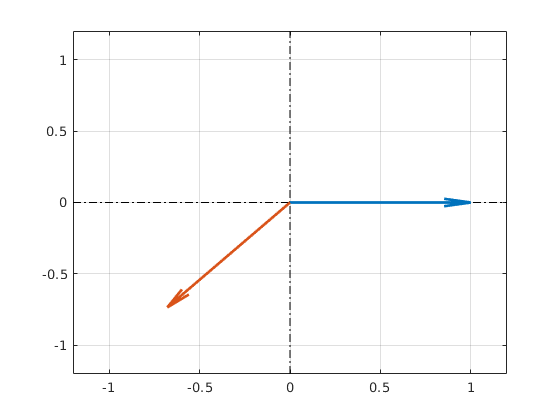

figure
X.plot(2,1);
Y1.plot(2,2);
box on

Действие матрицы S на элемент y1

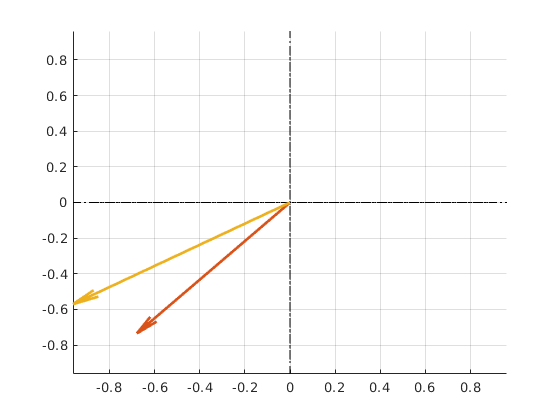

figure
Y1.plot(2,2);
Y2.plot(2,3);

Действие матрицы $\;U$ на элемент y2

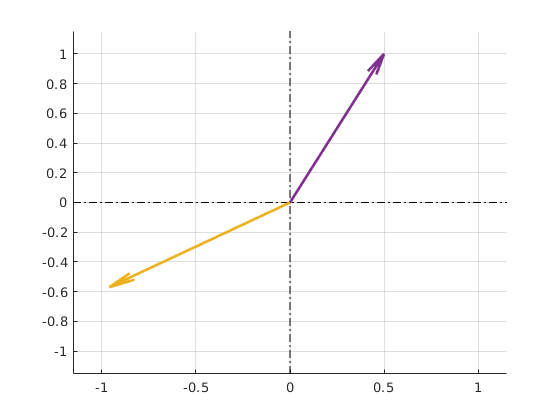

figure
Y2.plot(2,3);
Y3.plot(2,4);